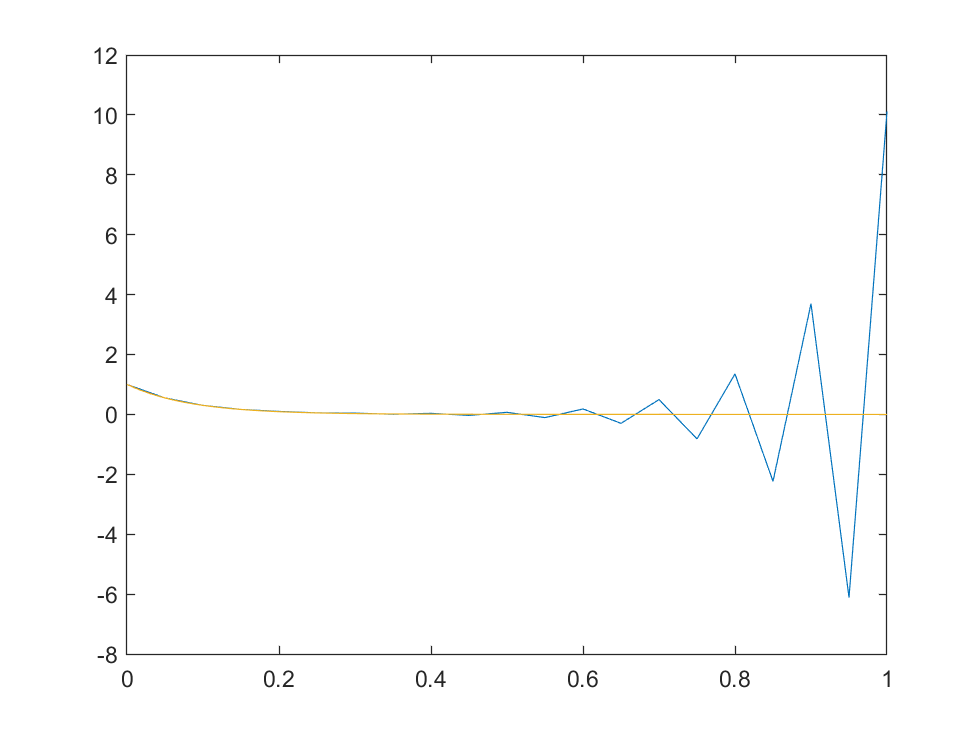

f =@(t,y) (-12*y);
F =@(t) (exp(-12*t));

a = 0;
b = 1;

alpha = 1;

N = [20,50,100];

y6 = AB4(f,a,b,alpha,N(1,1));
y7 = AB4(f,a,b,alpha,N(1,2));
y8 = AB4(f,a,b,alpha,N(1,3));

x6 = (b-a)/N(1,1);
x7 = (b-a)/N(1,2);
x8 = (b-a)/N(1,3);

t6 = a:x6:b;
t7 = a:x7:b;
t8 = a:x8:b;

t6 = t6';
t7 = t7';
t8 = t8';

plot(t6,y6,t7,y7,t8,y8);

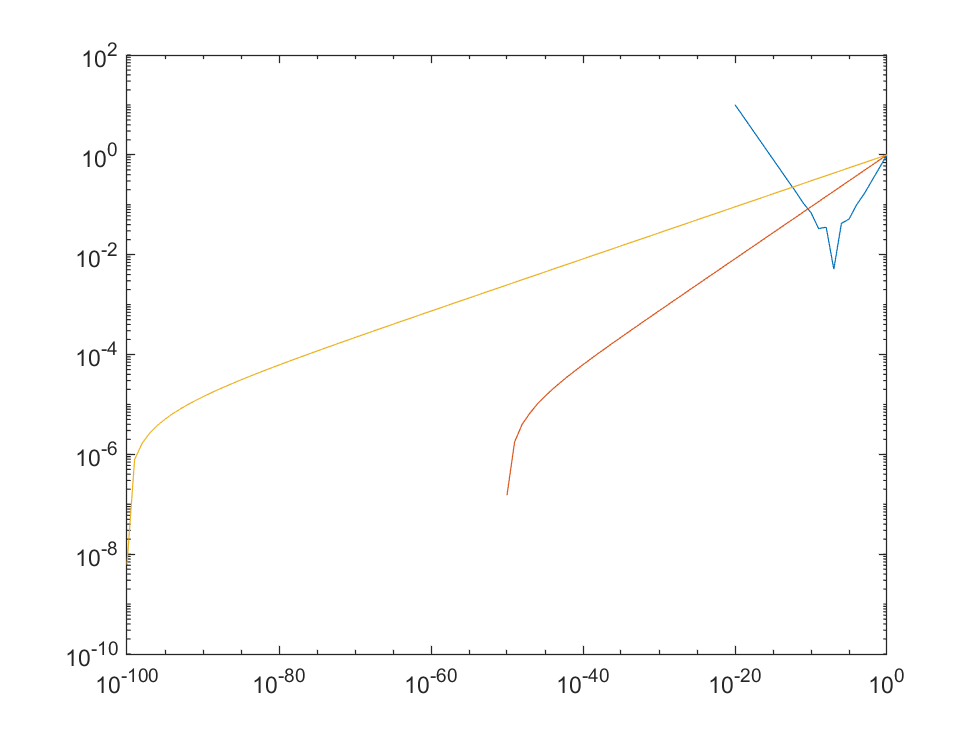


% the answer gets more accurate as the number of intervals increases

syms y(t)
eqn = diff(y,t) == (-12*y);
cond = y(0) == alpha;
ySol(t) = dsolve(eqn,cond);

eans = vpa(ySol(1));

h6 = ones(1,N(1,1)+1);
h7 = ones(1,N(1,2)+1);
h8 = ones(1,N(1,3)+1);

err6 = ones(1,N(1,1)+1);
err7 = ones(1,N(1,2)+1);
err8 = ones(1,N(1,3)+1);

% absolute error of 20 intervals
for i = 1:N(1,1)+1
    h6(1,i) = 10^(1-i);
    err6(1,i) = abs(eans-y6(i,1));
end

% absolute error of 50 intervals
for i = 1:N(1,2)+1
    h7(1,i) = 10^(1-i);
    err7(1,i) = abs(eans-y7(i,1));
end

% absolute error of 100 intervals
for i = 1:N(1,3)+1
    h8(1,i) = 10^(1-i);
    err8(1,i) = abs(eans-y8(i,1));
end

loglog(h6,err6);
hold on;
loglog(h7,err7);
loglog(h8,err8);
hold off;


Err2 = [err6(1,N(1,1)+1),err7(1,N(1,2)+1),err8(1,N(1,3)+1)];

% the error decreases as the number of intervals increases
% the method appears to be converging


function [y] = AB4(f,a,b,alpha,N)
    h = (b-a)/N;
    x = a:h:b;
    sx = size(x,2);
    y = ones(1,sx);
    y(1,1) = alpha;
    for i = 2:4
        k1 = h*f(x(1,i-1),y(1,i-1));
        k2 = h*f(x(1,i-1) + (h/2),y(1,i-1) + (k1/2));
        k3 = h*f(x(1,i-1) + (h/2),y(1,i-1) + (k2/2));
        k4 = h*f(x(1,i),y(1,i-1) + k3);
        y(1,i) = y(1,i-1) + (k1/6) + (k2/3) + (k3/3) + (k4/6);
    end
    for i = 5:N+1
        f1 = f(x(1,i-4),y(1,i-4));
        f2 = f(x(1,i-3),y(1,i-3));
        f3 = f(x(1,i-2),y(1,i-2));
        f4 = f(x(1,i-1),y(1,i-1));
        y(1,i) = y(1,i-1) + h*((55/24)*f4 - (59/24)*f3 + (37/24)*f2 - (3/8)*f1);
    end
    y = y';
end
